# Example: General elections in Austria 2024

Election date

electionDate = datetime('29-Sep-2024');

Parties

o = Parties.Oevp;
s = Parties.Spoe;
f = Parties.Fpoe;
g = Parties.Gruene;
n = Parties.Neos;
k = Parties.Kpoe;
b = Parties.Bier;
r = Parties.Rest;
allParties = enumeration('Parties');

## Polls

Source: [www.derstandard.at](http://www.derstandard.at) -> Umfragetracker

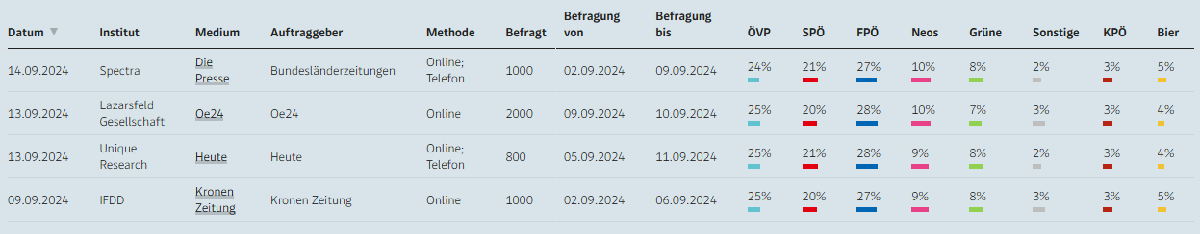

polls = Polls(allParties,Koala(electionDate));

% 14.09. (02.-09.09.) Spectra, by phone and online, 1000 respondents
addpoll(polls, datetime('06-Sep-2024'), 'Spectra', 1000, [o s f n g k b], [0.24 0.21 0.27 0.10 0.08 0.03 0.05]);

  06-Sep-2024, Spectra, 1000 Befragte:
	Spoe:	21.00 %
	Oevp:	24.00 %
	Gruene:	 8.00 %
	Fpoe:	27.00 %
	Neos:	10.00 %
	Kpoe:	 3.00 %
	Bier:	 5.00 %
	Rest:	 2.00 %



% 13.09. (09.09.-10.09.) Lazarsfeld, online, 2000 devalued to 1000 respondents
addpoll(polls, datetime('10-Sep-2024'), 'Lazarsfeld', 1000, [o s f n g k b], [0.25 0.20 0.28 0.10 0.07 0.03 0.04]);

  10-Sep-2024, Lazarsfeld, 1000 Befragte:
	Spoe:	20.00 %
	Oevp:	25.00 %
	Gruene:	 7.00 %
	Fpoe:	28.00 %
	Neos:	10.00 %
	Kpoe:	 3.00 %
	Bier:	 4.00 %
	Rest:	 3.00 %



% 13.09. (05.09.-11.09.) Unique Research, by phone and online, 800 respondents
addpoll(polls, datetime('08-Sep-2024'), 'Unique Research', 800, [o s f n g k b], [0.25 0.21 0.28 0.09 0.08 0.03 0.04]);

  08-Sep-2024, Unique Research, 800 Befragte:
	Spoe:	21.00 %
	Oevp:	25.00 %
	Gruene:	 8.00 %
	Fpoe:	28.00 %
	Neos:	 9.00 %
	Kpoe:	 3.00 %
	Bier:	 4.00 %
	Rest:	 2.00 %



% 09.09. (02.09.-06.09.) IFDD, online, 1000 devalued to 500 respondents
addpoll(polls, datetime('04-Sep-2024'), 'IFDD', 500, [o s f n g k b], [0.25 0.20 0.27 0.09 0.08 0.03 0.05]);

  04-Sep-2024, IFDD, 500 Befragte:
	Spoe:	20.00 %
	Oevp:	25.00 %
	Gruene:	 8.00 %
	Fpoe:	27.00 %
	Neos:	 9.00 %
	Kpoe:	 3.00 %
	Bier:	 5.00 %
	Rest:	 3.00 %



**=> Polls**

summary(polls)

    No       Date             Institute         Spoe    Oevp    Gruene    Fpoe    Neos    Kpoe    Bier    Rest     n  
    __    ___________    ___________________    ____    ____    ______    ____    ____    ____    ____    ____    ____

    1     04-Sep-2024    {'IFDD'           }     0.2    0.25     0.08     0.27    0.09    0.03    0.05    0.03     500
    2     06-Sep-2024    {'Spectra'        }    0.21    0.24     0.08     0.27     0.1    0.03    0.05    0.02    1000
    3     08-Sep-2024    {'Unique Research'}    0.21    0.25     0.08     0.28    0.09    0.03    0.04    0.02     

Estimate voting shares and effective sample size

[estimatedShares,neff] = evaluate(polls)

estimatedShares =     0.2055    0.2470    0.0770    0.2755    0.0961    0.0300    0.0445    0.0245


neff = 485

## Monte Carlo election simulation

nsim = 10000;
R = polls.dirsample(nsim);

Estimated distribution of voting shares

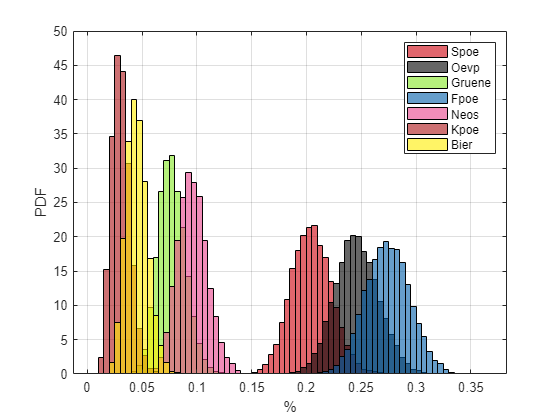

plotSample(polls,R)

## Bets

bs = BettingSlip(allParties);

**Bookmaker A**

Which party will receive the most votes?

addbet(bs, 'Bookmaker A', 1.50, f, 'max')

  Bookmaker A, meiste Stimmen Fpoe, Quote: 1.50



addbet(bs, 'Bookmaker A', 2.40, o, 'max')

  Bookmaker A, meiste Stimmen Oevp, Quote: 2.40



addbet(bs, 'Bookmaker A', 25.00, s, 'max')

  Bookmaker A, meiste Stimmen Spoe, Quote: 25.00



Over/Under %

- FPÖ

addbet(bs, 'Bookmaker A', 1.85, f, 'ltlim', 0.27);

  Bookmaker A, Fpoe < 27.00 %, Quote: 1.85



addbet(bs, 'Bookmaker A', 1.85, f, 'mtlim', 0.27);

  Bookmaker A, Fpoe > 27.00 %, Quote: 1.85



- ÖVP

addbet(bs, 'Bookmaker A', 1.95, o, 'ltlim', 0.245);

  Bookmaker A, Oevp < 24.50 %, Quote: 1.95



addbet(bs, 'Bookmaker A', 1.75, o, 'mtlim', 0.245); % s

  Bookmaker A, Oevp > 24.50 %, Quote: 1.75



- SPÖ

addbet(bs, 'Bookmaker A', 1.85, s, 'ltlim', 0.215);

  Bookmaker A, Spoe < 21.50 %, Quote: 1.85



addbet(bs, 'Bookmaker A', 1.85, s, 'mtlim', 0.215);

  Bookmaker A, Spoe > 21.50 %, Quote: 1.85



- NEOS

addbet(bs, 'Bookmaker A', 1.80, n, 'ltlim', 0.09);

  Bookmaker A, Neos < 9.00 %, Quote: 1.80



addbet(bs, 'Bookmaker A', 1.90, n, 'mtlim', 0.09);

  Bookmaker A, Neos > 9.00 %, Quote: 1.90



- GRÜNE

addbet(bs, 'Bookmaker A', 1.80, g, 'ltlim', 0.09);

  Bookmaker A, Gruene < 9.00 %, Quote: 1.80



addbet(bs, 'Bookmaker A', 1.90, g, 'mtlim', 0.09);

  Bookmaker A, Gruene > 9.00 %, Quote: 1.90



- Bierpartei

addbet(bs, 'Bookmaker A', 1.75, b, 'ltlim', 0.05);

  Bookmaker A, Bier < 5.00 %, Quote: 1.75



addbet(bs, 'Bookmaker A', 1.95, b, 'mtlim', 0.05);

  Bookmaker A, Bier > 5.00 %, Quote: 1.95



- KPÖ

addbet(bs, 'Bookmaker A', 1.75, k, 'ltlim', 0.025);

  Bookmaker A, Kpoe < 2.50 %, Quote: 1.75



addbet(bs, 'Bookmaker A', 1.95, k, 'mtlim',  0.025);

  Bookmaker A, Kpoe > 2.50 %, Quote: 1.95



**Bookmaker B**

Head-to-Head

- NEOS<>Die Grünen

bs.addbet('Bookmaker B', 1.70, n, 'mtparties', g);

  Bookmaker B, Gruene < Neos, Quote: 1.70



bs.addbet('Bookmaker B', 2.00, g, 'mtparties', n);

  Bookmaker B, Neos < Gruene, Quote: 2.00



- FPÖ<>SPÖ

bs.addbet('Bookmaker B', 1.02, f, 'mtparties', s);

  Bookmaker B, Spoe < Fpoe, Quote: 1.02



bs.addbet('Bookmaker B', 9.00, s, 'mtparties', f);

  Bookmaker B, Fpoe < Spoe, Quote: 9.00



- Bier<>KPÖ

bs.addbet('Bookmaker B', 1.15, b, 'mtparties', k);

  Bookmaker B, Kpoe < Bier, Quote: 1.15



bs.addbet('Bookmaker B', 4.75, k, 'mtparties', b);

  Bookmaker B, Bier < Kpoe, Quote: 4.75



- FPÖ<>ÖVP

bs.addbet('Bookmaker B', 1.55, f, 'mtparties', o);

  Bookmaker B, Oevp < Fpoe, Quote: 1.55



bs.addbet('Bookmaker B', 2.25, o, 'mtparties', f);

  Bookmaker B, Fpoe < Oevp, Quote: 2.25



- ÖVP<>SPÖ

bs.addbet('Bookmaker B', 1.12, o, 'mtparties', s);

  Bookmaker B, Spoe < Oevp, Quote: 1.12



bs.addbet('Bookmaker B', 5.25, s, 'mtparties', o);

  Bookmaker B, Oevp < Spoe, Quote: 5.25



Entry into the National Council (requires at least 4 %)

bs.addbet('Bookmaker B', 1.40, b, 'mtlim', 0.04)

  Bookmaker B, Bier > 4.00 %, Quote: 1.40



bs.addbet('Bookmaker B', 5.00, k, 'mtlim', 0.04)

  Bookmaker B, Kpoe > 4.00 %, Quote: 5.00



Which party will receive the most votes?

addbet(bs, 'Bookmaker B', 1.55, f, 'max')

  Bookmaker B, meiste Stimmen Fpoe, Quote: 1.55



addbet(bs, 'Bookmaker B', 2.25, o, 'max')

  Bookmaker B, meiste Stimmen Oevp, Quote: 2.25



addbet(bs, 'Bookmaker B', 30.00, s, 'max')

  Bookmaker B, meiste Stimmen Spoe, Quote: 30.00



Over/Under %

- FPÖ

bs.addbet('Bookmaker B', 1.83, f, 'ltlim', 0.265);

  Bookmaker B, Fpoe < 26.50 %, Quote: 1.83



bs.addbet('Bookmaker B', 1.83, f, 'mtlim', 0.265);

  Bookmaker B, Fpoe > 26.50 %, Quote: 1.83



- ÖVP

bs.addbet('Bookmaker B', 1.83, o, 'ltlim', 0.255);

  Bookmaker B, Oevp < 25.50 %, Quote: 1.83



bs.addbet('Bookmaker B', 1.83, o, 'mtlim', 0.255);

  Bookmaker B, Oevp > 25.50 %, Quote: 1.83



- SPÖ

bs.addbet('Bookmaker B', 1.83, s, 'ltlim', 0.215);

  Bookmaker B, Spoe < 21.50 %, Quote: 1.83



bs.addbet('Bookmaker B', 1.83, s, 'mtlim', 0.215);

  Bookmaker B, Spoe > 21.50 %, Quote: 1.83



- Die Grünen

bs.addbet('Bookmaker B', 1.83, n, 'ltlim', 0.09);

  Bookmaker B, Neos < 9.00 %, Quote: 1.83



bs.addbet('Bookmaker B', 1.83, n, 'mtlim', 0.09);

  Bookmaker B, Neos > 9.00 %, Quote: 1.83



- NEOS

bs.addbet('Bookmaker B', 1.83, n, 'ltlim', 0.095);

  Bookmaker B, Neos < 9.50 %, Quote: 1.83



bs.addbet('Bookmaker B', 1.83, n, 'mtlim', 0.095);

  Bookmaker B, Neos > 9.50 %, Quote: 1.83



- Bierpartei

bs.addbet('Bookmaker B', 1.83, b, 'ltlim', 0.0425);

  Bookmaker B, Bier < 4.25 %, Quote: 1.83



bs.addbet('Bookmaker B', 1.83, b, 'mtlim', 0.0425);

  Bookmaker B, Bier > 4.25 %, Quote: 1.83



**=> BettinSlip**

Total bet amount: 100

bs.Stake = 100;
summary(bs)

    No       Bookmaker             Description          Odds    Wager
    __    _______________    _______________________    ____    _____

     1    {'Bookmaker A'}    {'meiste Stimmen Fpoe'}     1.5    2.27 
     2    {'Bookmaker A'}    {'meiste Stimmen Oevp'}     2.4    2.27 
     3    {'Bookmaker A'}    {'meiste Stimmen Spoe'}      25    2.27 
     4    {'Bookmaker A'}    {'Fpoe < 27.00 %'     }    1.85    2.27 
     5    {'Bookmaker A'}    {'Fpoe > 27.00 %'     }    1.85    2.27 
     6    {'Bookmaker A'}    {'Oevp < 24.50 %'     }    1.95    2.27 
     7    {'Bookmaker A'}    {'Oevp > 24.50 %'     }    1.75    2.27 
     8    {'Bookmaker A'}    {'Spoe < 21.50 %'     }    1.85    2.27 
     9    {'Bookmaker A'}    {'Spoe > 21.50 %'     }    1.85    2.27 
    10    {'Bookmaker A'}    {'Neos < 9.00 %'      }     1.

## Optimization

Utility function: Selected indifference probability (100/-100) = 0.7

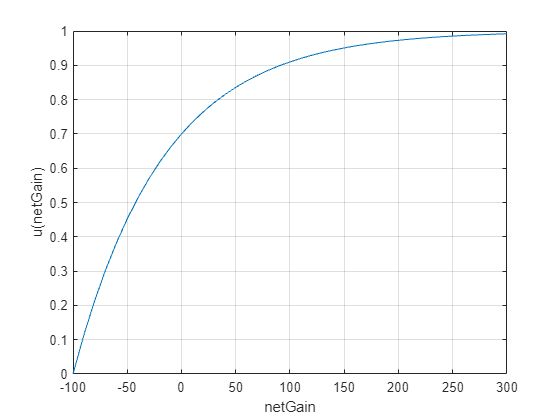

utilityFcn = @(netGain) exponentialUtility(netGain,0.7,bs.Stake);
x = -bs.Stake:10:3*bs.Stake;
plot(x,utilityFcn(x))
grid
xlabel('netGain')
ylabel('u(netGain)')

clear x

Cost function: Expected utility

fun = @(w) -mean(utilityFcn(bs.Stake * yield(bs,R,w)));

Parameters for the `fmincon` solver: Starting solution and constraints

w0 = ones(1,bs.NumberOfBets)/bs.NumberOfBets;
aeq = ones(1,bs.NumberOfBets);
beq = 1;
lb = zeros(bs.NumberOfBets,1);
ub = ones(bs.NumberOfBets,1);
options = optimoptions('fmincon','Display','iter');
options.MaxFunctionEvaluations = 10000;

## fmincon

wopt = fmincon(fun,w0,[],[],aeq,beq,lb,ub,[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      45   -6.320999e-01    3.331e-16    1.002e-01
    1      90   -6.391935e-01    8.882e-16    1.432e-02    6.062e-03
    2     135   -7.102530e-01    2.220e-16    7.727e-02    1.036e-01
    3     180   -7.502594e-01    2.220e-16    3.400e-02    1.133e-01
    4     225   -7.689574e-01    4.441e-16    9.429e-03    7.160e-02
    5     270   -7.708644e-01    1.110e-16    4.605e-03    1.289e-02
    6     315   -7.711327e-01    1.110e-16    3.972e-03    9.435e-03
    7     360   -7.711054e-01    0.000e+00    1.652e-03    1.457e-02
    8     405   -7.710352e-01    0.000e+00    1.000e-03    2.838e-03
    9     450   -7.861957e-01    0.000e+00    1.553e-02    8.271e-02
   10     495   -7.913700e-01    1.110e-16    4.635e-03    3.207e-02
   11     540   -7.916728e-01    0.000e+00    3.408e-03    7.573e-03
   12     585   -7.917117e-01    2.220e-16    1

wopt =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1493    0.0000    0.0000    0.0000    0.4067    0.0000    0.0447    0.0000    0.0000    0.1988    0.1144    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0854    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


## Optimization results - summary table

setWeights(bs,wopt);
[~,pwin] = iswon(bs,R);
sumTable = summary(bs);
sumTable.Wager = round(sumTable.Wager);
sumTable.pwin = pwin(:);
sumTable

sumTable = 44×6 table
    No       Bookmaker             Description          Odds    Wager     pwin 
    __    _______________    _______________________    ____    _____    ______

     1    {'Bookmaker A'}    {'meiste Stimmen Fpoe'}     1.5      0      0.7972
     2    {'Bookmaker A'}    {'meiste Stimmen Oevp'}     2.4      0      0.1974
     3    {'Bookmaker A'}    {'meiste Stimmen Spoe'}      25      0      0.0054
     4    {'Bookmaker A'}    {'Fpoe < 27.00 %'     }    1.85      0      0.4217
     5    {'Bookmaker A'}    {'Fpoe > 27.00 %'     }    1.85      0      0.5783
     6    {'Bookmaker A'}    {'Oevp < 24.50 %'     }    1.95      0      0.4884
     7    {'Bookmaker A'}    {'Oevp > 24.50 %'     }    1.75      0      0.5116
     8    {'Bookmaker A'}    {'Spoe < 21.50 %'     } 

## Optimization results - histogram

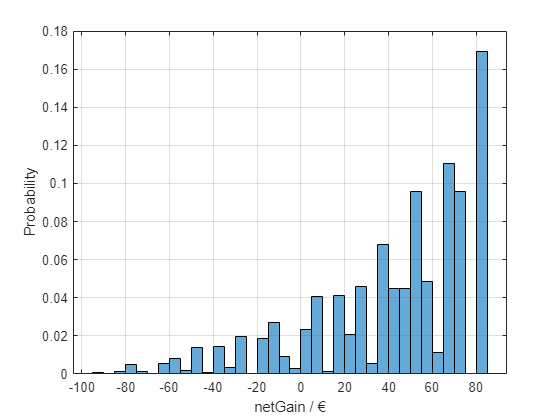

netGain = bs.Stake * yield(bs,R); % Calculation based on optimized weights
histogram(netGain,'Normalization','probability','BinWidth',5)
xlabel('netGain / €')
ylabel('Probability')
grid on

Probability of loss

sum(netGain < 0)/nsim

ans = 0.1331

Probability of winning

sum(netGain >= 0)/nsim

ans = 0.8669